raw_data = readtable('lab_2_part_2.csv'); 

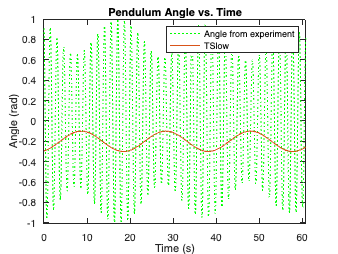

time_vals = rmmissing(raw_data.Time_s_0_2SameAngle);
angle_vals = rmmissing(raw_data.Angle_ChP1_rad_0_2SameAngle);
angle_vals_minus_mean = (angle_vals - mean(angle_vals));
angle_vals_minus_mean = angle_vals_minus_mean ./ max(angle_vals_minus_mean);
plot(time_vals, angle_vals_minus_mean,':', "Color", "green")
hold on 
fplot(@(x) 0.1*sin(0.32*x - 1.2) - 0.2, [min(time_vals), max(time_vals)])
% fplot(@(x) 0.1*sin(4.01*x - 1.2) + 0.2, [min(time_vals), max(time_vals)])
hold off
ylim([min(angle_vals_minus_mean), max(angle_vals_minus_mean)])
xlim([min(time_vals), max(time_vals)])
legend("Angle from experiment", "TSlow")
title("Pendulum Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (rad)")
% [x,y]=ginput
hold off

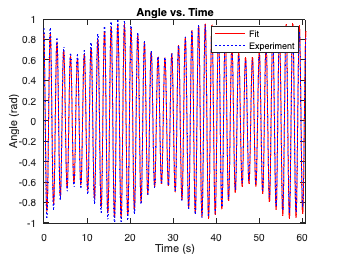

plot(fit_for_0_25_same_angle, "fit")
hold on
plot(time_vals, angle_vals_minus_mean,':', "Color", "blue")
title("Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Fit", "Experiment")
ylim([min(angle_vals_minus_mean), max(angle_vals_minus_mean)])
xlim([min(time_vals), max(time_vals)])
hold off

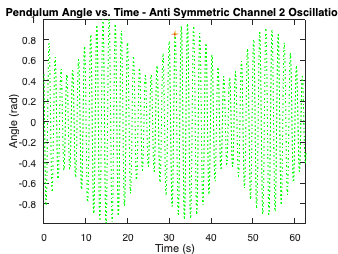


% process_and_plot_pendulum_vals(raw_data.Time_s_0_2SameAngle, raw_data.Angle_ChP1_rad_0_2SameAngle, "Symmetric Oscillation", 3.01)
% process_and_plot_pendulum_vals(raw_data.Time_s_0_2OppositeAngle, raw_data.Angle_ChP1_rad_0_2OppositeAngle, "Anti Symmetric Oscillation", 3.01)
process_and_plot_pendulum_vals(raw_data.Time_s_0_2OppositeAngle, raw_data.Angle_ChP2_rad_0_2OppositeAngle, "Anti Symmetric Channel 2 Oscillation", 3.01)

% process_and_plot_pendulum_vals(raw_data.Time_s_0_20, raw_data.Angle_ChP1_rad_0_20, "Compound Oscillation", 3.01)

function process_and_plot_pendulum_vals(x_vals, y_vals, input_title, frequency_fit)
    time_vals = rmmissing(x_vals);
    angle_vals = rmmissing(y_vals);
    smallest_input = min(length(time_vals), length(angle_vals));
    time_vals = time_vals(1:smallest_input);
    angle_vals = angle_vals(1:smallest_input);
    angle_vals_minus_mean = (angle_vals - mean(angle_vals));
    angle_vals_minus_mean = angle_vals_minus_mean ./ max(angle_vals_minus_mean);
    plot(time_vals, angle_vals_minus_mean,':', "Color", "green")
    hold on 
    errorbar(time_vals(smallest_input/2:smallest_input/2+1,1:1), angle_vals_minus_mean(smallest_input/2:smallest_input/2+1,1:1), 0.001, 0.001, 0.001, 0.001);
    hold on
    % fplot(@(x) 0.1*sin(frequency_fit*x - 1.2) - 0.2, [min(time_vals), max(time_vals)])
    title(strcat("Pendulum Angle vs. Time - ", input_title))
    xlabel("Time (s)")
    ylabel("Angle (rad)")
    ylim([min(angle_vals_minus_mean), max(angle_vals_minus_mean)])
    xlim([min(time_vals), max(time_vals)])

    cftool(time_vals, angle_vals_minus_mean, [], ones(1, length(time_vals)) * 0.0001)
    hold off
end
